# SINDy weak formulation: Kuramoto-Sivashinsky equation

Kuramoto-Sivashinsky equation: $\partial_t \;u+u\partial_x \;u+\partial_x^2 \;u+\partial_x^4 \;u=0$

KS equation describes: 

- chaotic dynamics of laminar flame fronts: G. Sivashinsky, Nonlinear analysis of hydrodynamic instability in laminar flames: I. derivation of basic equations, Acta Astronaut. 4, 1177 (1977).

- reaction-diffusion systems: Y. Kuramoto and T. Tsuzuki, Persistent propagation of concentration waves in dissipative media far from thermal equilibrium, Prog. Theor. Phys. 55, 356 (1976).

- coating flows: G. I. Sivashinsky and D. Michelson, On irregular wavy flow of a liquid film down a vertical plane, Prog. Theor. Phys. 63, 2112 (1980).

Data and code (modified) from Rudy et al (2017) and Reinbold et al (2020).

- Paper Rudy: [https://www.science.org/doi/10.1126/sciadv.1602614](https://www.science.org/doi/10.1126/sciadv.1602614) 

- Github Rudy: [https://github.com/snagcliffs/PDE-FIND](https://github.com/snagcliffs/PDE-FIND) 

- Paper Reinbold: [https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203](https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203) 

- Github Reinbold: [https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation](https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation)   

## Kuramoto-Sivashinsky data

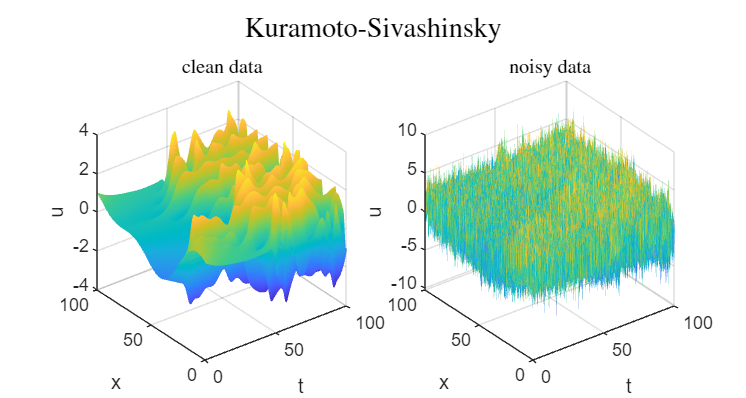

addpath(genpath(pwd))

% load data
traj = matfile('KS_data'); 

% grid densities
dt = traj.dt;
dx = traj.dx; 

% size of velocity fields
[Lx,Lt] = size(traj,'uu');

% add noise
sig = 0.0;
sig = 0.01;
sig = 1.0;

Ua = traj.uu; 
Ua = Ua + sig*std(Ua(:))*randn(size(Ua)); % Gaussian

% plot data
plotPDEdata(traj,Ua,'Kuramoto-Sivashinsky')

## Identify PDE with standard SINDy

% compute derivatives using finite difference
ut=[];
for xpos=1:size(Ua,1)
    ut(xpos,:)=FiniteDiff(real(Ua(xpos,:)),dt,1);
end

ux=[];uxx=[];uxxx=[];uxxxx=[];
for kk=1:size(Ua,2)
    ux(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,1);
    uxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,2);
    uxxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,3);
    uxxxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,4);
end


%% time derivatives: left hand side
LHS = -ut(:);

%% Library Theta: right hand side
const = ones(traj.Nt,traj.Nx);
u = Ua;
u2 = Ua.^2; 
u3 = Ua.^3;
% first order derivative ux 
uux = Ua.*ux; % advection term
u2ux = Ua.^2.*ux;
u3ux = Ua.^3.*ux;

Theta = [const(:), u(:), u2(:), u3(:), ux(:), uux(:), u2ux(:), u3ux(:), uxx(:), uxxx(:), uxxxx(:)];


% SINDy using sequentially trhesholding least squares
n = 1; % number of states
lambda = 0.05; % sparsification knob
Xi = sparsifyDynamics(Theta,LHS,lambda,n) % SINDy

Xi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% print coefficients
ThetaLIST = {'1','u','u^2','u^3','u_{x}','uu_{x}','u^2u_{x}','u^3u_{x}','u_{xx}','u_{xxx}','u_{xxxx}'}';
Xi_SINDy = [ThetaLIST, num2cell(Xi)]

Xi_SINDy = 11×2 cell array
    {'1'       }    {[0]}
    {'u'       }    {[0]}
    {'u^2'     }    {[0]}
    {'u^3'     }    {[0]}
    {'u_{x}'   }    {[0]}
    {'uu_{x}'  }    {[0]}
    {'u^2u_{x}'}    {[0]}
    {'u^3u_{x}'}    {[0]}
    {'u_{xx}'  }    {[0]}
    {'u_{xxx}' }    {[0]}
    {'u_{xxxx}'}    {[0]}



% error
c = ones(3,1); % KS true model coefficients
XiTrue = Xi([6 9 11]); % KS true model structure
error_SINDy = abs(XiTrue-c)./c % model coefficient error

error_SINDy =      1
     1
     1


nonZeroTermsSINDy = nnz(Xi) % number of nonzeros

nonZeroTermsSINDy = 0

# SINDy weak formulation

## Test function

% Discretization test function integration domain
Dx = 100;
Dt = 50;

% Create test function integration subdomain
x = linspace(-1,1,Dx+1); 
t = linspace(-1,1,Dt+1);

% integration domain size: domain from -1:1 -> dx*Dx = 2*Hx
Hx = dx*Dx/2; 
Ht = dt*Dt/2;

% number of integration domains
N_d = 100;

% Time and space sampling scheme: random integration domains
P = zeros(2,N_d);
P(1,:) = randi([1,Lx-Dx],N_d,1);
P(2,:) = randi([1,Lt-Dt],N_d,1);

% Initialize Target and Library
q0 = zeros(N_d,1);
Q = zeros(length(q0),8);
     

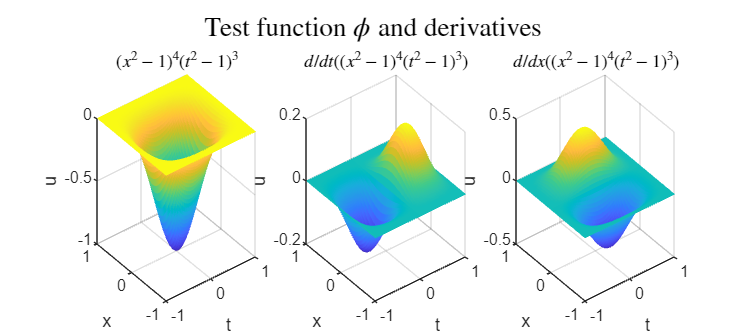

% Test functions phi = (x^2 - 1)^p_k * (t^2 - 1)^p_t
% derivatives: d/dx^k_x d/dt^k_t ( (x^2 - 1)^4 * (t^2 - 1)^3 )
% testFun([k_x,k_t],[p_x, p_t],x,t,Hx,Ht)
p = [4,3]; % test function exponents: 
phi00 = testFun([0,0],p,x,t,Hx,Ht); % (x^2 - 1)^4 * (t^2 - 1)^3
phi01 = testFun([0,1],p,x,t,Hx,Ht); % d/dt ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi10 = testFun([1,0],p,x,t,Hx,Ht); % d/dx ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi20 = testFun([2,0],p,x,t,Hx,Ht); % d/dx^2 ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi30 = testFun([3,0],p,x,t,Hx,Ht); % d/dx^3 ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi40 = testFun([4,0],p,x,t,Hx,Ht); % d/dx^4 ( (x^2 - 1)^4 * (t^2 - 1)^3 )

% plot test function
plotTF(x,t,phi00,phi01,phi10)

## Compute weak form target and library

% generate N_d weak form LHS (target) and RHS (library)
for np = 1:N_d  
    % Indices for integration domain
    rx = P(1,np):(P(1,np)+Dx);
    rt = P(2,np):(P(2,np)+Dt);

    % Velocity fields on integration domain
    U = Ua(rx,rt); 

    % Target: du/dt
    B = U.*phi01; 
    q0(np,1) = trapz(x,trapz(t,B,2),1); % numerical integration via the trapezoidal method
    
    % Theta = {'1','u','u^2','u^3','u_{x}','uu_{x}','u^2u_{x}','u^3u_{x}','u_{xx}','u_{xxx}','u_{xxxx}'}';
    % const
    th = phi00; 
    Q(np,1) = trapz(x,trapz(t,th,2),1);
    % Linear Term
    th = U.*phi00;
    Q(np,2) = trapz(x,trapz(t,th,2),1);
    % Quadratic Term
    th = U.^2.*phi00;
    Q(np,3) = trapz(x,trapz(t,th,2),1);
    % Cubic Term
    th = U.^3.*phi00;
    Q(np,4) = trapz(x,trapz(t,th,2),1);
    % First Order Derivative
    th = U.*phi10;
    Q(np,5) = trapz(x,trapz(t,th,2),1);
    % Advection Term: uux
    th = -(1/2)*U.^2.*phi10; 
    Q(np,6) = trapz(x,trapz(t,th,2),1);
    % u2ux
    th = -(1/3)*U.^3.*phi10; 
    Q(np,7) = trapz(x,trapz(t,th,2),1);
    % u3ux
    th = -(1/4)*U.^4.*phi10; 
    Q(np,8) = trapz(x,trapz(t,th,2),1);
    % Second Order Derivative: Laplacian Term
    th = U.*phi20;
    Q(np,9) = trapz(x,trapz(t,th,2),1);
    % Third Order Derivative
    th = U.*phi30;
    Q(np,10) = trapz(x,trapz(t,th,2),1);
    % Fourth Order Derivative: Biharmonic Term
    th = U.*phi40; 
    Q(np,11) = trapz(x,trapz(t,th,2),1);    
end
            

## Identify PDE with weak form SINDy

Xi = sparsifyDynamics(Q, q0, lambda,n); % SINDy

% print coefficients
Xi_wSINDy = [ThetaLIST, num2cell(Xi)]

Xi_wSINDy = 11×2 cell array
    {'1'       }    {[     0]}
    {'u'       }    {[     0]}
    {'u^2'     }    {[     0]}
    {'u^3'     }    {[     0]}
    {'u_{x}'   }    {[     0]}
    {'uu_{x}'  }    {[0.9141]}
    {'u^2u_{x}'}    {[     0]}
    {'u^3u_{x}'}    {[     0]}
    {'u_{xx}'  }    {[0.8933]}
    {'u_{xxx}' }    {[     0]}
    {'u_{xxxx}'}    {[0.8846]}



% error
XiTrue = Xi([6 9 11]); % KS true model structure
error_weakSINDy = abs(XiTrue-c)./c % model coefficient error

error_weakSINDy =     0.0859
    0.1067
    0.1154


nonZeroTermsWeakSINDy = nnz(Xi) % number of nonzeros

nonZeroTermsWeakSINDy = 3